## Задание 2. Фильтрация звука.

**Ваша задача: выполнить фильтрацию сигнала таким образом, чтобы остался только голос. **

**Читаем аудиофайл**

[y,f] = audioread('MUHA.wav');
% sound(y,f); % play the sound -- original

**Получаем массив точек времени**

dt = 1/f; % Шаг времени
T = length(y)*dt % Длительность аудиофайла

T = 5.6305

t = 0 : dt : T-dt; % Время (всего length(y) точек)

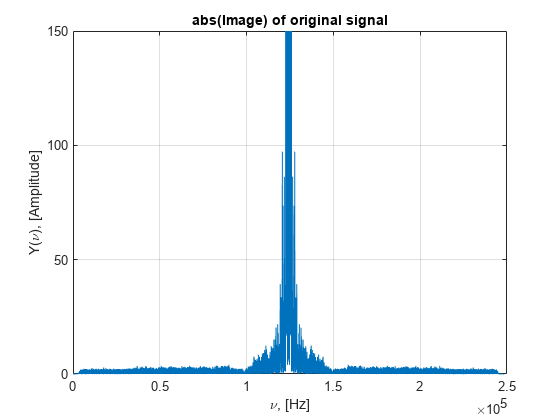

% Apply the filter to the signal
Y = fftshift(fft(y));

plot(abs(Y))
grid on;
title("abs(Image) of original signal")
xlabel('\nu, [Hz]');
ylabel('Y(\nu), [Amplitude]');
ylim([0, 150])
path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
Name = "task2_image1";
fullpath = fullfile(path, Name);
saveas(gcf, fullpath, 'png');



dv = 1/T; % Шаг частоты 
v = -f/2 : dv : f/2 -1/T; % Набор частот, половину ведь ухо даже не слышит (правило дискретизации частот для ПК)
g_t = zeros(size(Y));

fc_low = 350; % Cutoff freq in Hz
fc_high = 3000; % Cutoff freq in Hz

g_t((v >= fc_low) & (v <= fc_high)) = 1; % setting up the filter

Y_filtered = Y.*g_t;
pure = real(ifft(ifftshift(Y_filtered)));

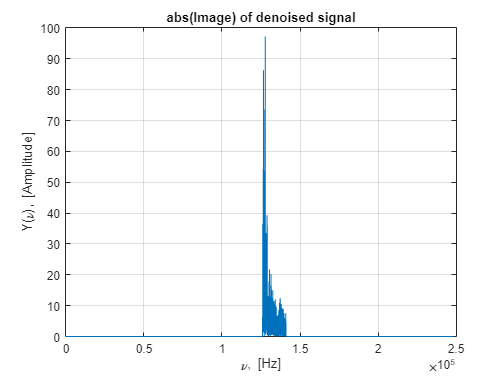

plot(abs((Y_filtered)))
grid on;
title("abs(Image) of denoised signal")
xlabel('\nu, [Hz]');
ylabel('Y(\nu), [Amplitude]');
ylim([0, 100])
xlim("auto")
path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
Name = "task2_image2";
fullpath = fullfile(path, Name);
saveas(gcf, fullpath, 'png');

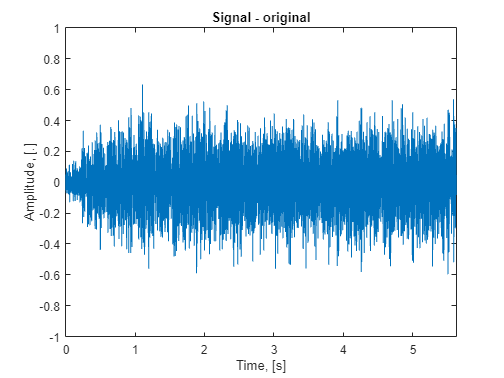

plot(t,y)
title("Signal - original")
xlabel("Time, [s]")
ylabel("Amplitude, [.]")
xlim("tight")
ylim([-1 1])
path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
Name = "task2_signal1";
fullpath = fullfile(path, Name);
saveas(gcf, fullpath, 'png');

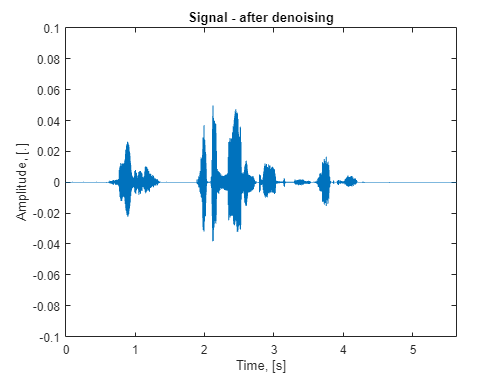



plot(t,pure)
title("Signal - after denoising")
xlabel("Time, [s]")
ylabel("Amplitude, [.]")
xlim("tight")
ylim([-0.1; 0.1])
path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
Name = "task2_signal2";
fullpath = fullfile(path, Name);
saveas(gcf, fullpath, 'png');

**Проигрываем очищенный звук**

sound(pure,f); % play the sound

% Задайте значения параметров a, t1 и t2
a = 3;
t1 = -2;
t2 = 4;

Теперь возьмём большой интервал времени $T$ и маленький шаг дискретизации $\textrm{dt}$

T = 20;
dt = 0.01;
% Создайте диапазон значений t
t=-T/2:dt:T/2;

Найдём зашумлённую версию сигнала как


$$u=g+b*\left(\textrm{rand}\left(\textrm{size}\left(t\right)\right)-0\ldotp 5\right)+c*\sin \left(d*t\right);$$


% зададим дополнительные коэффиценты - на рандом пока что
b = 1; 
c = 0; 
d = 0;

Построим график фильтра

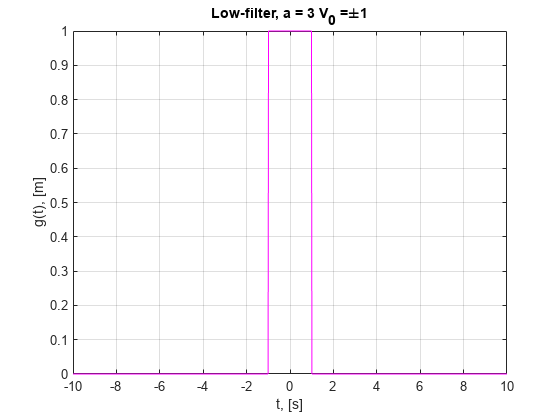

% Зададим диапазон чистки --> [-V0; V0]
V0 = T/20;
V1 = T/10;
plotFilter(1, t, V0,V1, a);

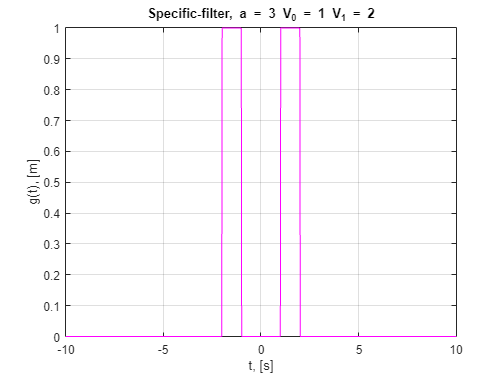

plotFilter(2, t, V0,V1, a);

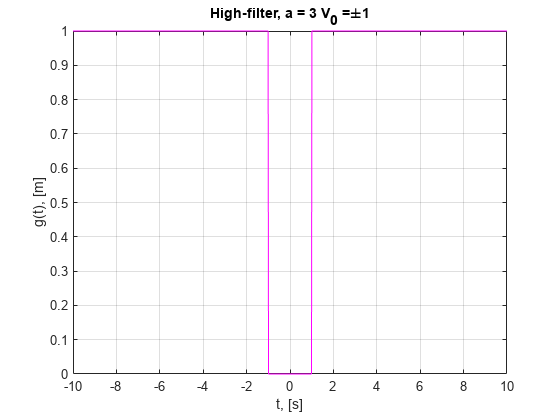

plotFilter(3, t, V0,V1, a);

Получим зашумлённый сигнал и его образ ниже

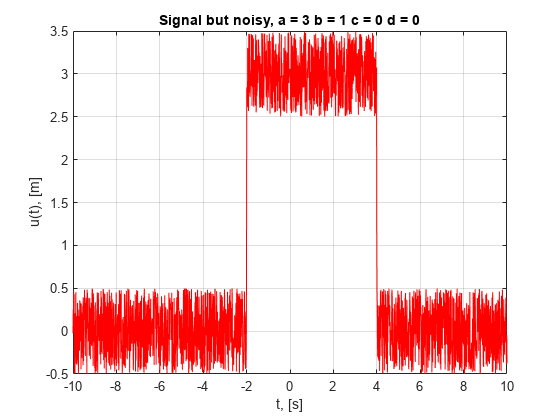

u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
U = fftshift(fft(u)); % Прямое преобразование (быстрое)
plotSignal(t, t1,t2, a,b,c,d)

Давайте ограничим область видимых частот, чтобы сделать график визуально приятнее

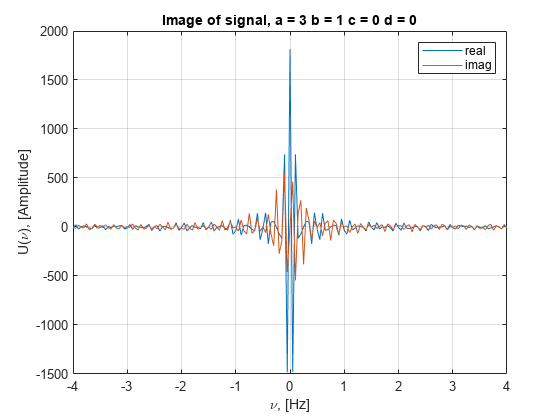

plotImage(t, t1,t2, a,b,c,d,  dt, T)

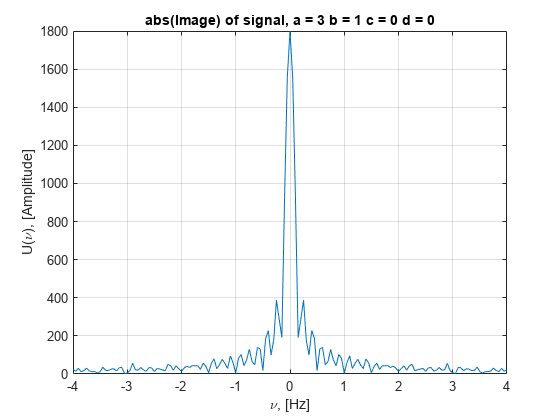

plotAbsImage(t, t1,t2, a,b,c,d,  dt, T)

### Убираем специфические частоты

**1 испытание**

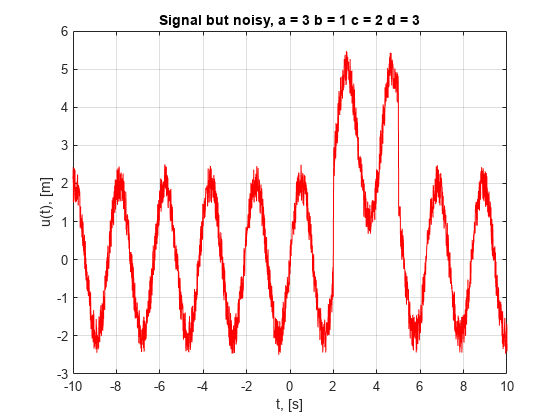

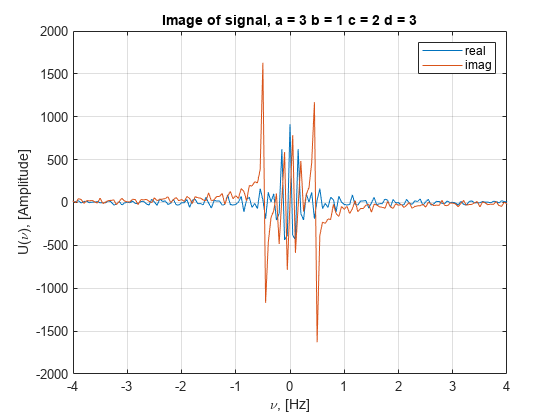

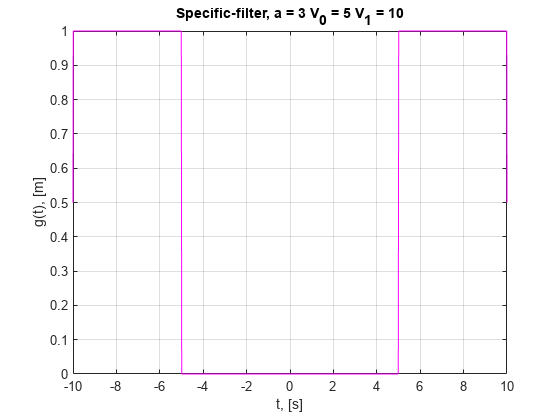

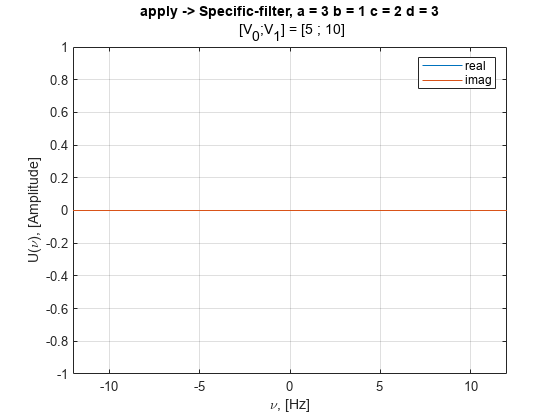

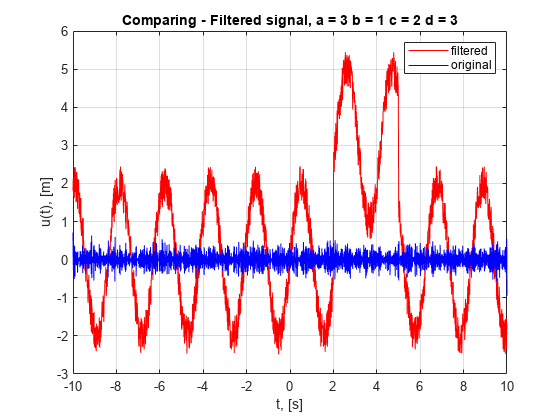

b=1;c=2;d=3; t1=2; t2=5; V0 = T/4; V1 = T/2;
analysis(2, t, t1,t2, a,b,c,d, dt, T, V0, V1)

##  Все функции, используемые в скрипте

### Первое задание

***Вспомогательная функция для помех***

function y = g(t, a, t1, t2)
    y = a * (heaviside(t - t1) - heaviside(t - t2));
end

**Фильтр высоких частот**

function y = g_inv(t, V0)
y = 1 - (heaviside(t + V0) - heaviside(t - V0));
end

**Фильтр специфических частот**

function y = g_even(t, V0, V1)
    y = (heaviside(t - V0) - heaviside(t - V1)) + (heaviside(-t - V0) - heaviside(-t - V1));
end

**Фильтр низких частот**

function y = g_odd(t, V0)
    y = (heaviside(t + V0) - heaviside(t - V0));
end

Функция для построения графика **фильтра **

function plotFilter(select, t, V0,V1, a)
    figure( randi([1 3000],1,1) )

    if (select == 1)
        g_t = g_odd(t, V0);
    elseif (select == 2)
        g_t = g_even(t, V0, V1);
    else
        g_t = g_inv(t, V0);
    end
    plot(t, g_t, 'magenta');

    if (select == 1)
        title("Low-filter, " + "a = "+a+" V_0 =\pm"+V0)
    elseif (select == 2)
        title("Specific-filter, " + "a = "+a+" V_0 = "+V0+" V_1 = "+V1)
    else
        title("High-filter, " + "a = "+a+" V_0 =\pm"+V0)
    end

    grid on
    xlabel('t, [s]');
    ylabel('g(t), [m]');
    hold off;
    
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
    Name = "filter_a=" + a+"_V0="+V0+"_V1="+V1;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');
end

Функция для построения графика сигнала

function plotSignal(t, t1,t2, a,b,c,d)
    figure( randi([1 3000],1,1) )

    u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
    plot(t, u, 'red');
    title("Signal but noisy, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d)
    grid on;
%     xlim([t1, t2]);
    xlabel('t, [s]');
    ylabel('u(t), [m]');
    hold off;
    
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
    Name = "signal_a=" + a+"_b="+b+"_c="+c+"_d="+d;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');
end

Функция для построения графика модуля образа сигнала

function plotAbsImage(t, t1,t2, a,b,c,d, dt, T)
    figure( randi([1 3000],1,1) )
    u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
    U = fftshift(fft(u));
    
    V = 1/dt; % Ширина диапазона частот
    dv = 1/T; % Шаг частоты 
    v = -V/2 : dv : V/2; % Набор частот для FFT

    plot(v, abs(U));
    xlim([-4; 4]);
    title("abs(Image) of signal, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d)
    grid on;
    xlabel('\nu, [Hz]');
    ylabel('U(\nu), [Amplitude]');
    hold off;
    
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
    Name = "abs_image_a=" + a+"_b="+b+"_c="+c+"_d="+d;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');
end

Функция для построения графика образа сигнала - вещественных и комплексных компонент

function plotImage(t, t1,t2, a,b,c,d, dt, T)
    figure( randi([1 3000],1,1) )
    u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);

    U = fftshift(fft(u));
    
    V = 1/dt; % Ширина диапазона частот
    dv = 1/T; % Шаг частоты 
    v = -V/2 : dv : V/2; % Набор частот для FFT

    plot(v, real(U));
    hold on
    plot(v, imag(U));
    legend('real','imag')
    xlim([-4; 4]);
    title("Image of signal, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d)
    grid on;
    xlabel('\nu, [Hz]');
    ylabel('U(\nu), [Amplitude]');
    hold off;
    
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
    Name = "image_a=" + a+"_b="+b+"_c="+c+"_d="+d;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');
end

Функция для применение **фильтра** на образы сигнала - вещественное и комплексное

function applyFilter(select, t, t1,t2, a,b,c,d, dt, T, V0, V1)
    figure( randi([1 3000],1,1) )

    u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
    U = fftshift(fft(u));
    
     if (select == 1)
        g_t = g_odd(t, V0);
    elseif (select == 2)
        g_t = g_even(t, V0, V1);
    else
        g_t = g_inv(t, V0);
    end


    V = 1/dt; % Ширина диапазона частот
    dv = 1/T; % Шаг частоты 
    v = -V/2 : dv : V/2; % Набор частот для FFT
    
    plot(v, real(U).*g_t);
    hold on
    plot(v, imag(U).*g_t);
    legend('real','imag')
    xlim([-12; 12]);
    if (select == 1)
        title("apply -> Low-filter, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d , {" V_0 =\pm"+V0})
    elseif (select == 2)
        title("apply -> Specific-filter, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d , {" [V_0;V_1] = ["+V0+" ; "+V1+"]"})
    else
        title("apply -> High-filter, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d , {" V_0 =\pm"+V0})
    end

    grid on;
    xlabel('\nu, [Hz]');
    ylabel('U(\nu), [Amplitude]');
    hold off;
    
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
    Name = "applied_filter_a=" + a+"_b="+b+"_c="+c+"_d="+d;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');
end

Функция для отрисовка графика "чистого" сигнала после фильтрации

function plotPure(select, t, t1,t2, a,b,c,d, V0, V1)
    figure( randi([1 3000],1,1) )
    u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
    U = fftshift(fft(u));
    
     if (select == 1)
        g_t = g_odd(t, V0);
    elseif (select == 2)
        g_t = g_even(t, V0, V1);
    else
        g_t = g_inv(t, V0);
    end

    pure = U.*g_t;
    u_new = ifft(ifftshift(pure)); % Обратное преобразование
    plot(t, u, 'red');
    hold on;
    plot(t, u_new, 'blue');
    title("Comparing - Filtered signal, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d)
    legend('filtered', 'original')
    grid on
%     xlim([t1, t2]);
    xlabel('t, [s]');
    ylabel('u(t), [m]');
    hold off;
    
    % in one fucntion ???
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
    Name = "pure_signal_a=" + a+"_b="+b+"_c="+c+"_d="+d;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');
end


Мета-функция для быстрого анализа по первому заданию:

function analysis(select, t, t1,t2, a,b,c,d, dt, T, V0, V1)
    plotSignal(t, t1,t2, a,b,c,d);
    plotImage(t, t1,t2, a,b,c,d, dt, T);
    plotFilter(select, t, V0,V1, a);
    applyFilter(select, t, t1,t2, a,b,c,d, dt, T, V0, V1);
    plotPure(select, t, t1,t2, a,b,c,d, V0, V1);
end



###  Второе задание